# **Payload Performance Analysis (CoDPAD M2)**

**CoDPAD module 2 : Payload Performance Analysis**

본 장에서는 검사시 활용하는 payload의 성능을 평가한다. Payload 성능평가는 김발의 기본동적특성을 분석하는 부분을 다룬다. 

[CoDPAD Ch. 2 - Confluence](https://nearth.atlassian.net/l/c/jsFMKKDf)

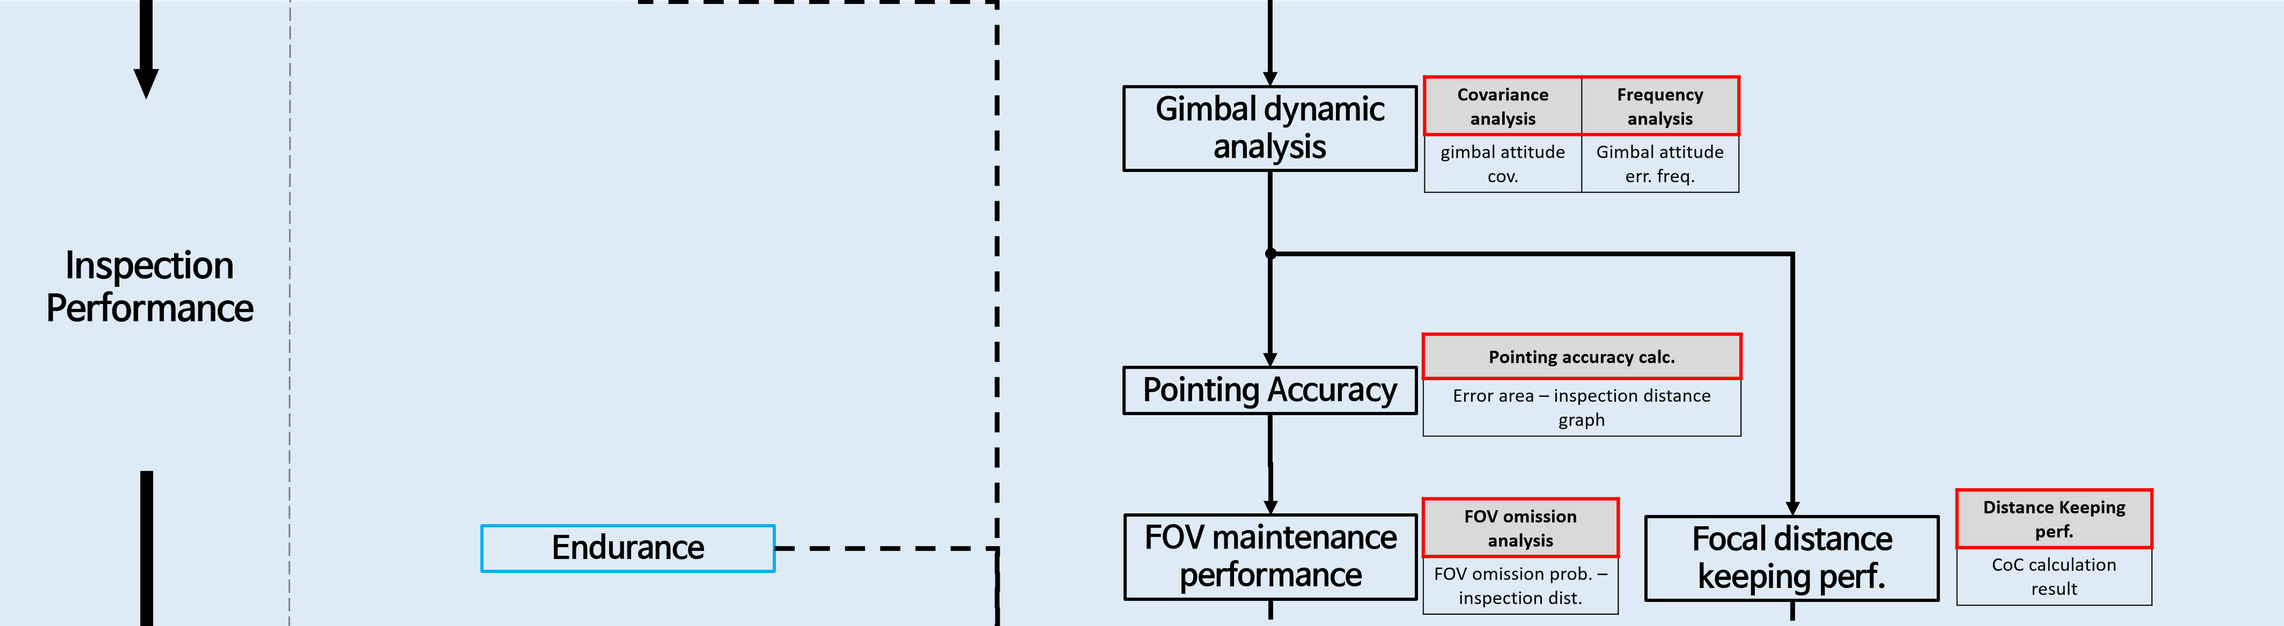

cd(fileparts(matlab.desktop.editor.getActiveFilename))
d2r = pi/180

d2r = 0.0175

## **User Input**

**index guide**

1: gimbal Roll

2: gimbal Pitch

3: gimbal Yaw

4: gimbalRollCmd

5: gimbalPitchCmd

6: gimbalYawCmd

Insert Gimbal Test Data Address

gimbalDataAddr = "/home/jaehan/log/221115_095700/gdLog_221115_095700.csv"

gimbalDataAddr = "/home/jaehan/log/221115_095700/gdLog_221115_095700.csv"

Check if the aircraft is 'isYawFixed' type. (M300)

isYawFixed = true

isYawFixed = logical
   1



inspectionDistance = 9

inspectionDistance = 9

confidence = 0.9

confidence = 0.9000

global calcDensity
calcDensity = 300

calcDensity = 300

## APPENDIX

Gimbal system transfer function model :


$$(K_p + {K_I \over s} + K_ds) {1\over {Is^2}} \over 1 + (K_p + {K_I \over s} + K_ds) {1\over {Is^2}$$


Reference : [PoC 김발 system ID.](https://nearth.atlassian.net/wiki/spaces/nearthlab/pages/2237923407/Payload+test+PoC+system+ID.)

## Data Parsing

gimbalData = readtable(gimbalDataAddr);
gimbalTime = gimbalData.rosTime - gimbalData.rosTime(1);
gimbalTime = seconds(gimbalTime);

testStartFlag = [];
testFinishFlag = [];
missionStartFlag = [];
missionFinishFlag = [];
fcMode = gimbalData.fcMcMode;
missionType = gimbalData.missionType;

ns = 1; nf = 1; nsm = 1; nfm = 1;
for i = 2:length(fcMode)
    if fcMode(i) ~= fcMode(i-1) && fcMode(i) == 2
        testStartFlag(ns) = i; ns = ns+1;
    elseif fcMode(i) ~= fcMode(i-1) && fcMode(i-1) == 2
        testFinishFlag(nf) = i; nf = nf+1;
    end
    if fcMode(i-1) == 0 && fcMode(i) == 1
        missionStartFlag(nsm) = i; nsm = nsm + 1;
    elseif fcMode(i-1) == 1 && fcMode(i) == 0
        missionFinishFlag(nfm) = i; nfm = nfm + 1;
    end
end

cmdSet = [gimbalData.gimbalRpyCmd_deg_0, gimbalData.gimbalRpyCmd_deg_1, gimbalData.gimbalRpyCmd_deg_2];
if isYawFixed
   cmdSet = [gimbalData.gimbalRpyCmd_deg_0, gimbalData.gimbalRpyCmd_deg_1, gimbalData.yawSp_deg];
end    
responseSet = [gimbalData.gimbalRpy_deg_0,gimbalData.gimbalRpy_deg_1,gimbalData.gimbalRpy_deg_2];

gimSteadyData = responseSet(1:2000,:);
gimCov = cov(gimSteadyData); %%TODO
if isYawFixed
    gimCov = gimCov(1:2,1:2);
end

## Gimbal Sensing Characteristics

### Gimbal encoding resolution

temp = diff(gimbalData.gimbalRpy_deg_0);
minResRoll = min(abs(temp(diff(gimbalData.gimbalRpy_deg_0)~=0)));

temp = diff(gimbalData.gimbalRpy_deg_1);
minResPitch = min(abs(temp(diff(gimbalData.gimbalRpy_deg_1)~=0)));
if ~isYawFixed
    minResYaw = min(abs(temp(diff(gimbalData.gimbalRpy_deg_2)~=0)))
else
    disp("No yaw resolution information provided : yawFixedVehicle.")
end

No yaw resolution information provided : yawFixedVehicle.


columns = {'Roll','Pitch','Yaw'};
rows = {'Encoding resolution'};
if ~isYawFixed
    T = table(minResRoll,minResPitch,minResYaw,'Rownames',rows);
else
    T = table(minResRoll,minResPitch,"N/A",'Rownames',rows);
end
T.Properties.VariableNames = columns

T = 1×3 table
                             Roll       Pitch       Yaw 
                           ________    ________    _____

    Encoding resolution    0.021972    0.021972    "N/A"


## Gimbal Response Plot

### Roll Step Test

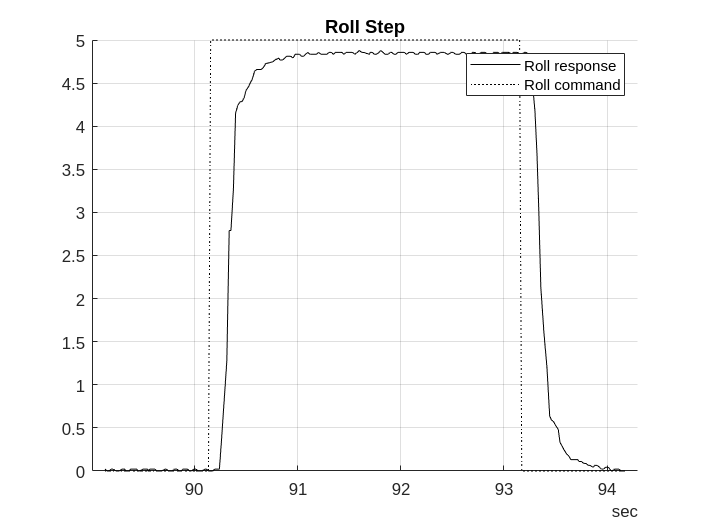

range = testStartFlag(3):testFinishFlag(3);
figure(1)
clf
hold on
grid on
title('Roll Step')
plot(gimbalTime(range),gimbalData.gimbalRpy_deg_0(range),'k')
plot(gimbalTime(range),gimbalData.gimbalRpyCmd_deg_0(range),'k:')
legend('Roll response','Roll command')

### Pitch Step Test

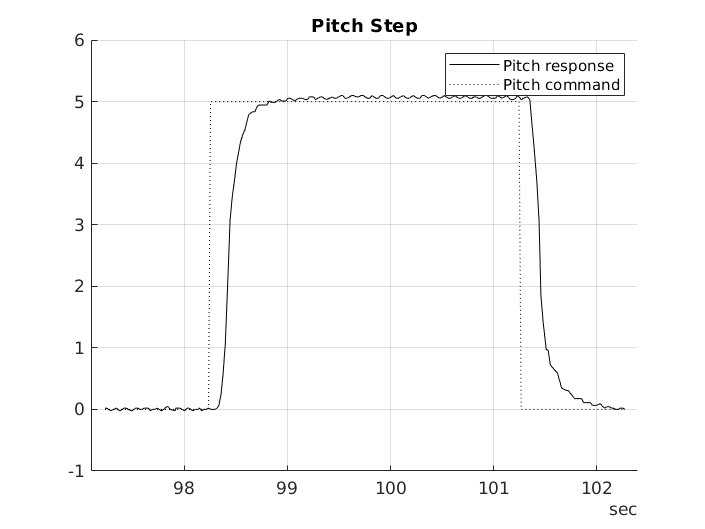

range = testStartFlag(4):testFinishFlag(4);
figure(2)
clf
hold on
grid on
title('Pitch Step')
plot(gimbalTime(range),gimbalData.gimbalRpy_deg_1(range),'k')
plot(gimbalTime(range),gimbalData.gimbalRpyCmd_deg_1(range),'k:')
legend('Pitch response','Pitch command')

### Roll Sweep Test

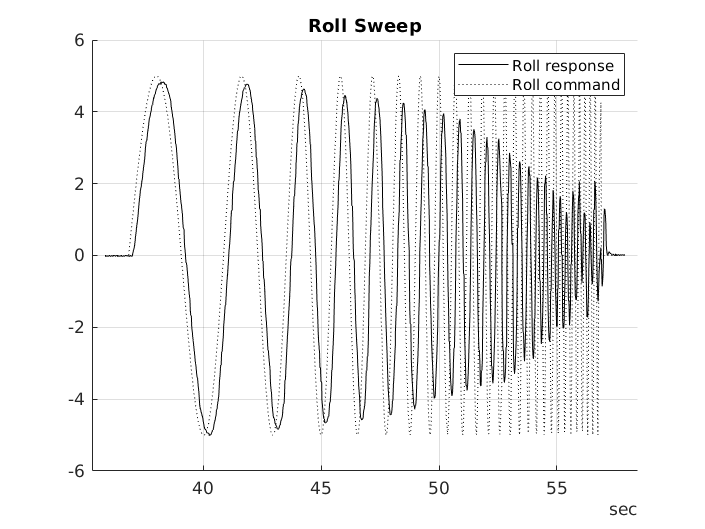

range = testStartFlag(1):testFinishFlag(1);
figure(3)
clf
hold on
grid on
title('Roll Sweep')
plot(gimbalTime(range),gimbalData.gimbalRpy_deg_0(range),'k')
plot(gimbalTime(range),gimbalData.gimbalRpyCmd_deg_0(range),'k:')
legend('Roll response','Roll command')

### Pitch Sweep Test

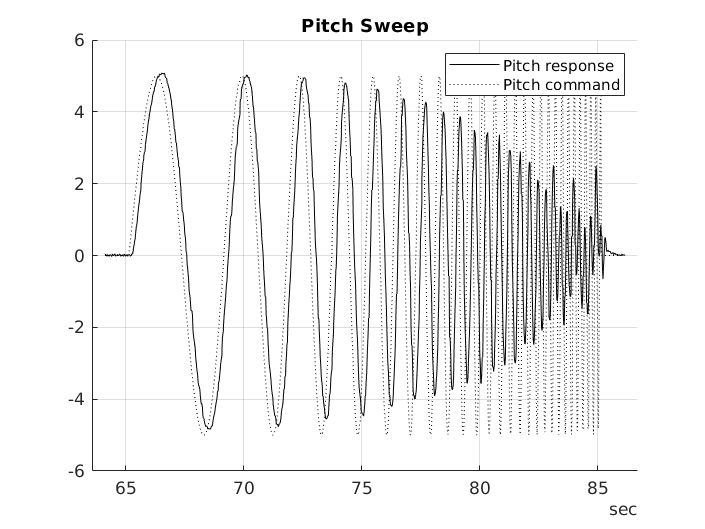

range = testStartFlag(2):testFinishFlag(2);
figure(4)
clf
hold on
grid on
title('Pitch Sweep')
plot(gimbalTime(range),gimbalData.gimbalRpy_deg_1(range),'k')
plot(gimbalTime(range),gimbalData.gimbalRpyCmd_deg_1(range),'k:')
legend('Pitch response','Pitch command')

## Gimbal Dynamic Characteristics

This part suggests the gimbal's basic dynamic characteristics and analyzes the gimbal attitude error occuring during steady-state flight situation. Also, the interference characteristic between the vehicle and the payload is also suggested using transfer function estimation algorithm.

### Basic dynamic characteristic

global nN nD
nN = 2;
nD = 3;

gimResult = {};
for i = 3:4 % only step test
    [Num,Den,delay]=estimate_tf(i,responseSet,cmdSet,testStartFlag,testFinishFlag);
    gimResult{i-2}.Num = Num;
    gimResult{i-2}.Den = Den;
    gimResult{i-2}.Delay = delay;
    A = [num2str(i-2),'th transfer function estimation complete'];
    disp(A)
    sys = tf(gimResult{i-2}.Num,gimResult{i-2}.Den,'ioDelay',gimResult{i-2}.Delay)
end

1th transfer function estimation complete


sys =
 
                  4.269 s^2 + 353.2 s + 5149
  exp(-0.1*s) * ------------------------------
                s^3 + 36.54 s^2 + 862 s + 5310
 
Continuous-time transfer function.



2th transfer function estimation complete


sys =
 
                   2.22 s^2 + 454.9 s + 9712
  exp(-0.1*s) * -------------------------------
                s^3 + 45.27 s^2 + 1382 s + 9589
 
Continuous-time transfer function.



save('gimResult.mat', 'gimResult')

#### Step response

Step response of transfer functions estimated from previous section is shown below.

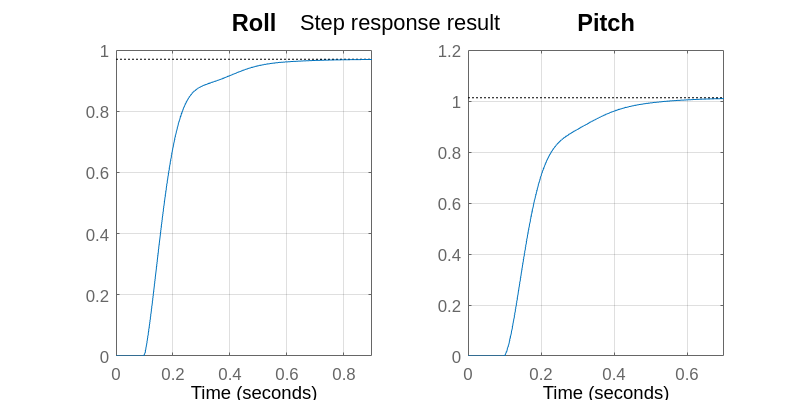

gimStepResult = {}; gimPhaseResult = {};
dataSize = size(gimResult,2);
dataName = {'Roll','Pitch'};

figure(5)
clf
set(gcf,'Position',[10 10 800 400])
for i = 1:dataSize
    sys = tf(gimResult{i}.Num,gimResult{i}.Den,'ioDelay',gimResult{i}.Delay);
    gimStepResult{i} = stepinfo(sys);
    [gm,pm,wg,wp] = margin(sys);
    gimPhaseResult{i} = [gm,pm,wg,wp,bandwidth(sys)];
    subplot(1,2,i)
    hold on
    step(sys)
    grid on    
    title(dataName{i},'fontsize',14)
    ylabel('');
end
sgtitle('Step response result') 
hold off



gimStepResultTable = [];
for i = 1:dataSize
    gimStepResultTable(i,1) = gimStepResult{i}.RiseTime;
    gimStepResultTable(i,2) = gimStepResult{i}.SettlingTime;
    gimStepResultTable(i,3) = gimStepResult{i}.Overshoot;
    gimStepResultTable(i,4) = gimStepResult{i}.Peak;
    temp = step(tf(gimResult{i}.Num,gimResult{i}.Den,'ioDelay',gimResult{i}.Delay));
    gimStepResultTable(i,5) = 1 - temp(end);
end

Basic step response characteristics are calculated using 'step' function provided by MATLAB, and with the help of other basic functions. For detailed definition of the terms introduced in this section, please refer to the following document.

[Link : Step response definitions](https://kr.mathworks.com/help/control/ref/stepinfo.html)

columns = {'Rise time','Settling time','Overshoot','Peak','SSE'};
if isYawFixed
    rows = {'Roll','Pitch'};
else
    rows = {'Roll','Pitch','Yaw'};
end
T = table(gimStepResultTable(:,1),gimStepResultTable(:,2),gimStepResultTable(:,3),gimStepResultTable(:,4),gimStepResultTable(:,5),'Rownames',rows);
T.Properties.VariableNames = columns

T = 2×5 table
             Rise time    Settling time    Overshoot     Peak         SSE    
             _________    _____________    _________    _______    __________

    Roll      0.1679         0.50919           0        0.96969      0.031858
    Pitch      0.208         0.49982           0         1.0128    -0.0094164


#### Frequency response

Frequency response of a system can be analyzed using Bode plot. Bode plots of transfer functions are shown below.

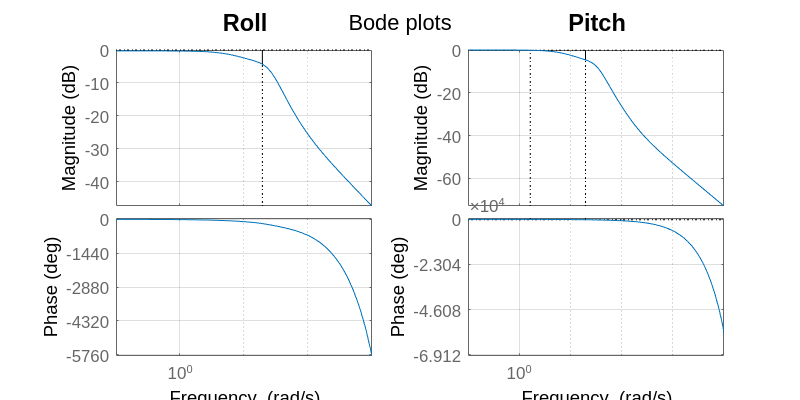

gimPhaseResultTable = [];
for i = 1:dataSize
    gimPhaseResultTable(i,1) = gimPhaseResult{i}(1);
    gimPhaseResultTable(i,2) = gimPhaseResult{i}(2);
    gimPhaseResultTable(i,3) = gimPhaseResult{i}(3);
    gimPhaseResultTable(i,4) = gimPhaseResult{i}(4);
    gimPhaseResultTable(i,5) = gimPhaseResult{i}(5);
end

figure(6)
clf
set(gcf,'Position',[10 10 800 400])
for i = 1:dataSize
    sys = tf(gimResult{i}.Num,gimResult{i}.Den,'ioDelay',gimResult{i}.Delay);
    subplot(1,2,i)
    hold on
    margin(sys)
    grid on
    title(dataName{i},'fontsize',14)
end
sgtitle('Bode plots') 
hold off

Frequency response is calculated using 'margin' function provided by MATLAB. For further detail, please refer to the following document.

[Link : Margin function explanation](https://kr.mathworks.com/help/control/ref/margin.html?searchHighlight=margin&s_tid=srchtitle)

columns = {'Gain Margin','Phase Margin','BandWidth'};
if isYawFixed
    rows = {'Roll','Pitch'};
else
    rows = {'Roll','Pitch','Yaw'};
end
T = table(gimPhaseResultTable(:,1),gimPhaseResultTable(:,2),gimPhaseResultTable(:,5),'Rownames',rows);
T.Properties.VariableNames = columns

T = 2×3 table
             Gain Margin    Phase Margin    BandWidth
             ___________    ____________    _________

    Roll       1.6383             Inf         14.26  
    Pitch      1.6802          161.52        11.954  


## Total Error (Knowledge + Performance) Analysis

### Knowledge Reliability Area

if isYawFixed
    stateSize = 2;
else
    stateSize = 3;
end
    
gimbalHoldSampleData = mvnrnd(zeros(stateSize,1),gimCov,10000);

% Gimbal Pointing Accuracy calculation
gimbalRoll = gimbalHoldSampleData(:,1) * d2r;
gimbalPitch = gimbalHoldSampleData(:,2) * d2r;
% gimbalYaw = gimbalHoldSampleData(:,3) * d2r;

err_x_p = inspectionDistance .* gimbalPitch .* sin(gimbalRoll);
err_y_p = inspectionDistance .* gimbalPitch .* cos(gimbalRoll);

% Multivariate Analysis
[pos_confidence_area,pos_out,pos_maxPdf,pos_peripheral,pos_X,pos_Y] = multiVariateAnalysis(err_x_p,err_y_p,confidence);
A = [num2str(confidence*100),'% confidence area is ',num2str(pos_confidence_area),' [m^2]'];
disp(A);

90% confidence area is 2.553e-06 [m^2]


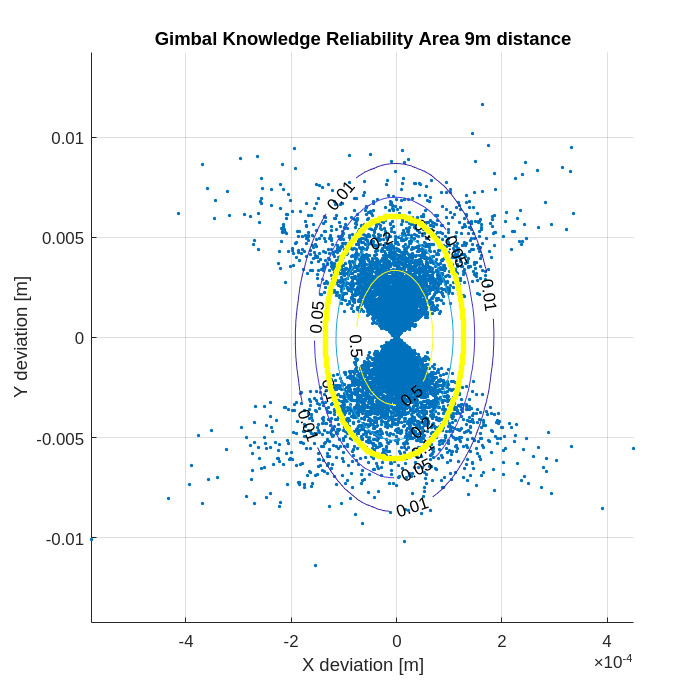

posEdgeIdx = convhull(pos_peripheral);

figure(7)
clf
hold on
plot(err_x_p,err_y_p,'.')

contour(pos_X,pos_Y,pos_out/pos_maxPdf,[0.5 0.2 0.1 0.05 0.01],'ShowText','on')
grid on
plot(pos_peripheral(:,1),pos_peripheral(:,2),'.y','MarkerSize',10)
plot(pos_peripheral(posEdgeIdx,1),pos_peripheral(posEdgeIdx,2),'y-')
% axis equal
titleText = ['Gimbal Knowledge Reliability Area ', num2str(inspectionDistance), 'm distance'];
title(titleText);
xlabel('X deviation [m]')
ylabel('Y deviation [m]')
set(gcf,'Position',[10 10 700 700])

## Function definition

function [Num, Den, delay] = estimate_tf(n,responseSet,cmdSet,testStartFlag,testFinishFlag)
global nN nD

Cmd = cmdSet(testStartFlag(n):testFinishFlag(n)-1,n-2);
Response = responseSet(testStartFlag(n):testFinishFlag(n)-1,n-2);

timeseriesSet = iddata(Response,Cmd,0.02);
sys = tfest(timeseriesSet,nD,nN,nan);
Num = sys.Numerator;
Den = sys.Denominator;
delay = sys.IODelay;
end

function [confidence_area,out,maxPdf,peripheral,X,Y] = multiVariateAnalysis(x_data,y_data,confidence)
% Internal parameters : DO NOT TOUCH
global calcDensity
level = 1-confidence;
zRange = 5;
cumulated = 0;
index = [];
peripheral = [];
density = calcDensity;

% calculate maxpdf
mu_x = mean(x_data);
mu_y = mean(y_data);
std_x = std(x_data);
std_y = std(y_data);
covar = cov([x_data,y_data]);

maxPdf = mvnpdf([mu_x mu_y],[mu_x mu_y],covar);
thres = level * maxPdf;

% distribution data for plotting
[X,Y] = meshgrid(linspace(mu_x-std_x*zRange,mu_x+std_x*zRange,50),linspace(mu_y-std_y*zRange,mu_y+std_y*zRange,50));
out = BiNorm(X,Y,[mu_x;mu_y],covar);

% distribution data for prob. calc.
xGrid = linspace(mu_x-zRange*std_x,mu_x+zRange*std_x,density);
yGrid = linspace(mu_y-zRange*std_y,mu_y+zRange*std_y,density);
xGrid(end) = [];
yGrid(end) = [];
xGridSize = xGrid(2)-xGrid(1);
yGridSize = yGrid(2)-yGrid(1);
gridArea = xGridSize * yGridSize;

for i = xGrid
    for j = yGrid
        if mvnpdf([i j],[mu_x mu_y],covar) >= thres
            cumulated = cumulated + mvncdf([i j],[i+xGridSize j+yGridSize],[mu_x mu_y],covar);
            index = vertcat(index,[i,j]);
        end
    end
end

% cumulated % for verification. This value must be equal to 'confidence' param.

for i = 1:length(index)
    if boxed(i,index,xGridSize,yGridSize)
        peripheral = vertcat(peripheral,index(i,:));
    end
end

confidence_area = length(index) * gridArea;
end

function flag = boxed(n,index,xGridSize,yGridSize)
x = index(n,1); y = index(n,2);
right = 0; left = 0; up = 0; down = 0;
flag = 0;

if isempty(find(abs(index(:,1)-(x+xGridSize)) < xGridSize/2 & abs(index(:,2)-y) < yGridSize/2,1))
    right = 1;
end
if isempty(find(abs(index(:,1)-(x-xGridSize)) < xGridSize/2 & abs(index(:,2)-y) < yGridSize/2,1))
    left = 1;
end
if isempty(find(abs(index(:,1)-x) < xGridSize/2 & abs(index(:,2)-(y+yGridSize)) < yGridSize/2,1))
    up = 1;
end
if isempty(find(abs(index(:,1)-x) < xGridSize/2 & abs(index(:,2)-(y-yGridSize)) < yGridSize/2,1))
    down = 1;
end

if up || down || right || left
    flag = 1;
end

end
